fs = 48000;
N = 101;
f_low = 2000;       % suppress hum/rumbles
f_high = 10000;     % preserve voice range, cut hiss

h = bandpass_fir(f_low, f_high, fs, N);             % design filter
x_filtered = conv(x, h, 'same');          % apply FIR filter via convolution

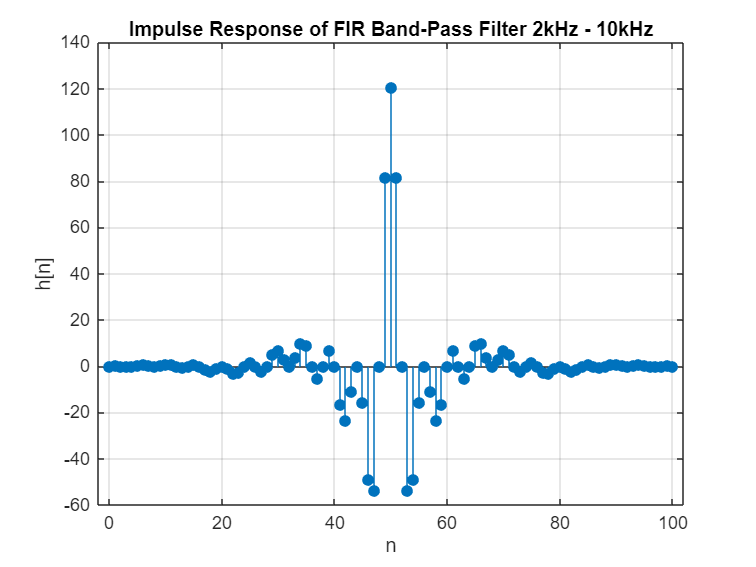

figure;
stem(0:N-1, h, 'filled');
xlabel('n'); ylabel('h[n]');
title('Impulse Response of FIR Band-Pass Filter 2kHz - 10kHz');
grid on;

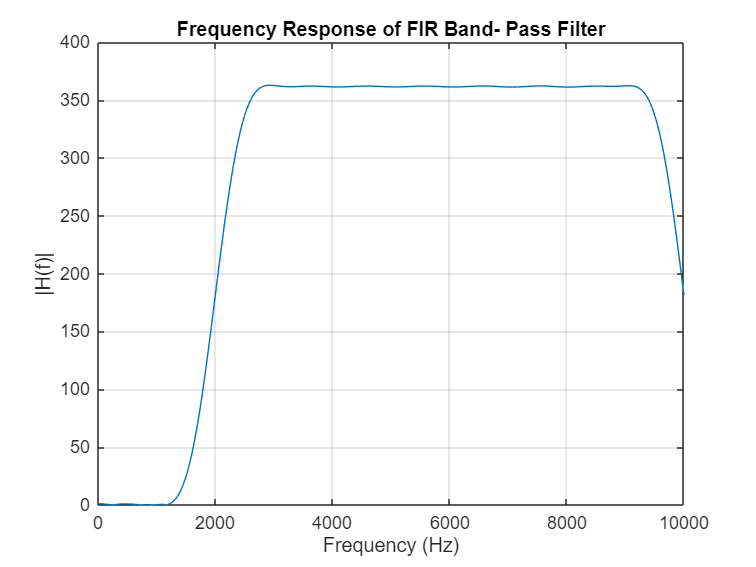

% Frequency axis (same as FFT)
N_fft = 1024;
f_axis = (0:N_fft-1) * fs / N_fft;

% Compute FFT of filter
H_f = abs(fft(h, N_fft));

% Plot
figure;
plot(f_axis, H_f);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Frequency Response of FIR Band- Pass Filter');
xlim([0 10000]);
grid on;

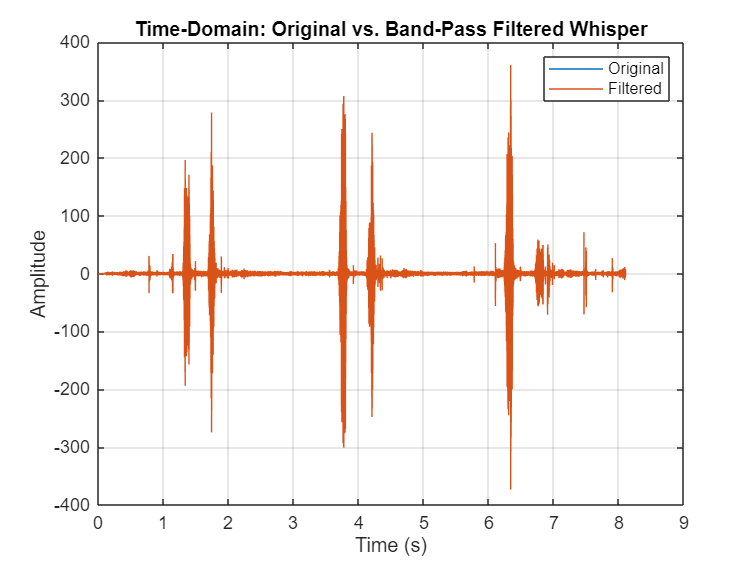

figure;
plot(t, x); hold on;
plot(t, x_filtered);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Original vs. Band-Pass Filtered Whisper');
legend('Original','Filtered');
grid on;

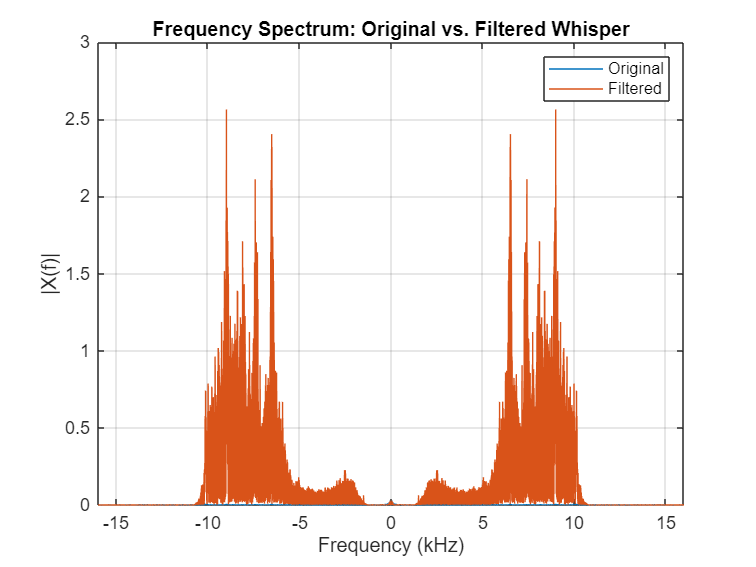

[~, xf_filtered, ~] = ftr(t, x_filtered, T, 'fft');

figure;
plot(f/1000, abs(xf)); hold on;
plot(f/1000, abs(xf_filtered));
xlabel('Frequency (kHz)');
ylabel('|X(f)|');
title('Frequency Spectrum: Original vs. Filtered Whisper');
legend('Original','Filtered');
xlim([-16, 16]);
grid on;

x_filtered = x_filtered / max(abs(x_filtered));
audiowrite('whisper_filtered_bandpass.wav', x_filtered, fs);